load('baseballstats.mat', 'Batting');

One of the first things that I want to do is divide the Batting table up by year. I use the findgroups() command. Here, I use [findgroups() and splitapply() ](http://blogs.mathworks.com/loren/2015/11/03/analyzing-baby-names-with-matlab-r2015b/#5c0cf125-9854-47d6-a1d3-e9cb0371cd01)to find the max number of doubles in each season over time

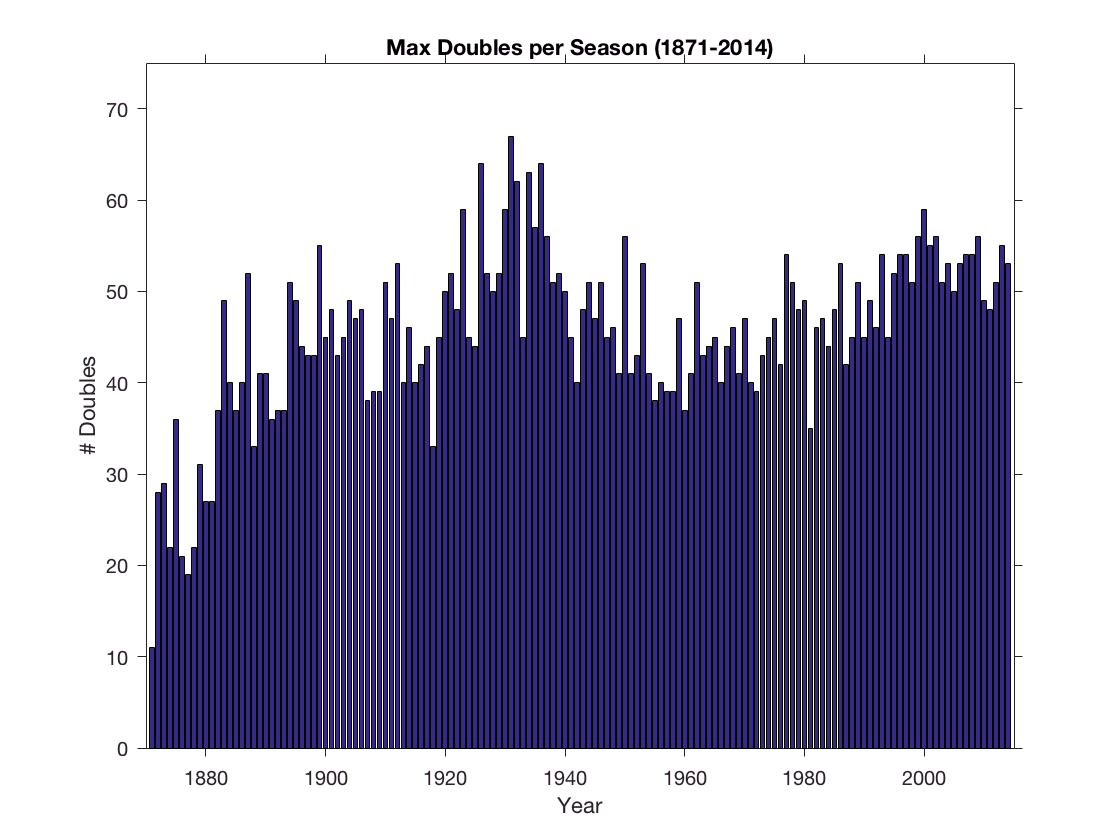

%% start batting analysis
Gyear = findgroups(Batting.yearID);
figure
bar(unique(Batting.yearID), splitapply(@max, Batting.x2B, Gyear));
title('Max Doubles per Season (1871-2014)')
ax = gca;
ax.TickDir = 'out';
ax.YLim = [0 75];
ax.XLim = [1870 2015];
ax.XLabel.String = 'Year';
ax.YLabel.String = '# Doubles';
print('images/doublesovertime.png', '-dpng');

Now I want to see if there is a correlation between the maximum number of doubles and the total number of hits

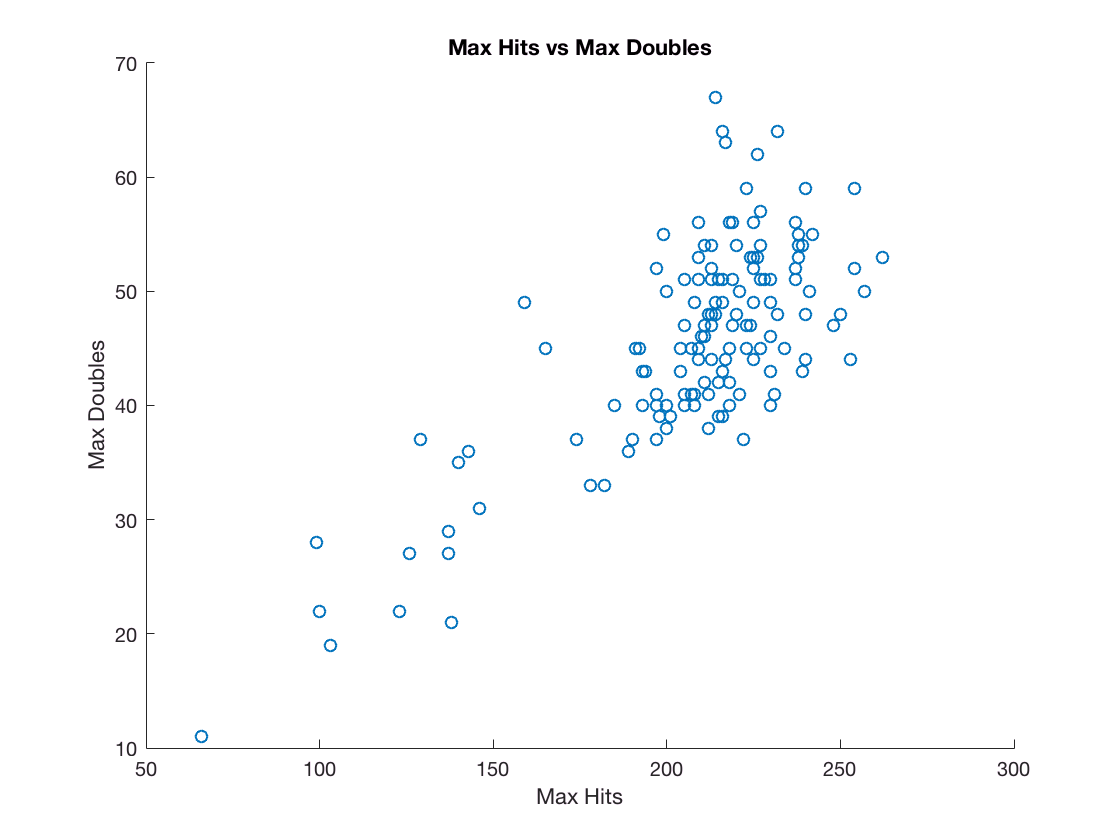

figure
scatter(splitapply(@max, Batting.H, Gyear), splitapply(@max, Batting.x2B, Gyear));
title('Max Hits vs Max Doubles');
ax = gca;
ax.XLabel.String = 'Max Hits';
ax.YLabel.String = 'Max Doubles';
print('images/maxhitsvsmaxdoubles.png', '-dpng');

Now lets see if we can find Pete Rose

[Gplayer, players] = findgroups(Batting.playerID);
[~, idx] = max(splitapply(@sum, Batting.H, Gplayer));
getPlayerName(players(idx))

ans =     nameFirst    nameLast
    _________    ________
    'Pete'       'Rose'  

Let's make a boxplot showing offensive stats over the last ten years for the Phillies.

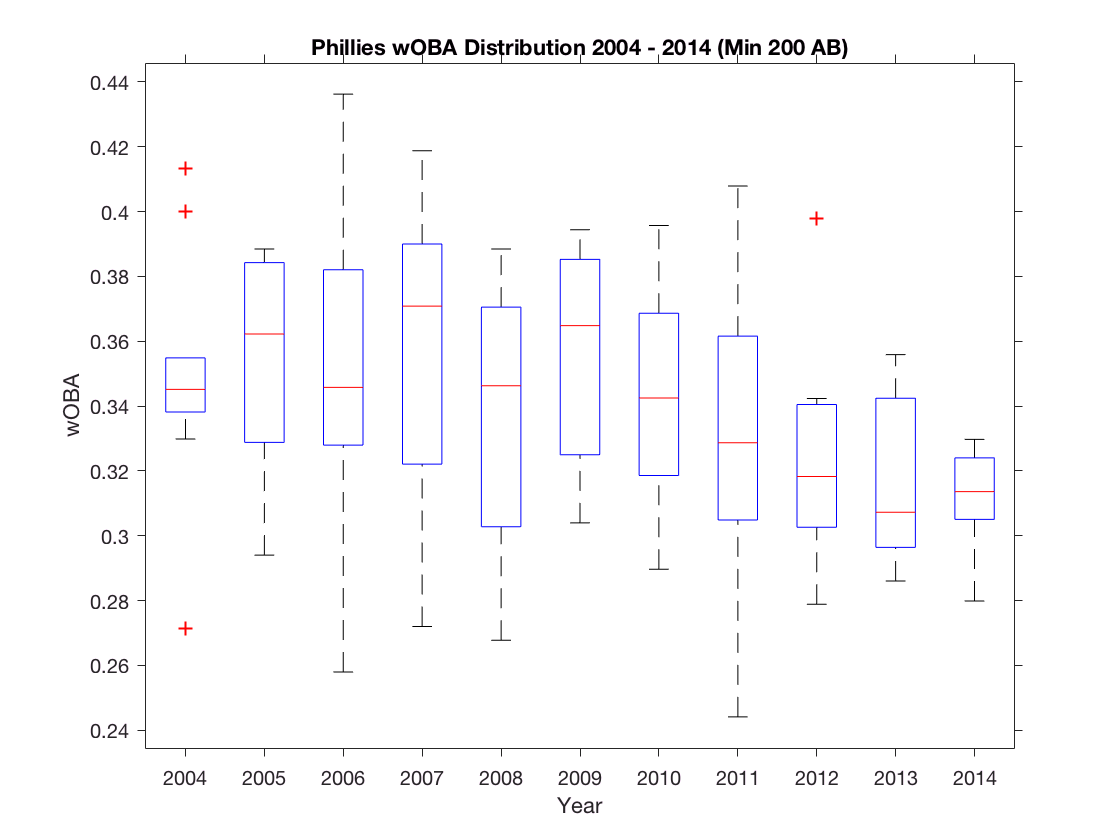

Phillies = Batting(Batting.teamID == 'PHI' & Batting.yearID >= 2004 & Batting.yearID <= 2015 & Batting.AB >= 200, :);
figure
boxplot(Phillies.wOBA, Phillies.yearID);
title('Phillies wOBA Distribution 2004 - 2014 (Min 200 AB)');
ax = gca;
ax.XLabel.String = 'Year';
ax.YLabel.String = 'wOBA';
ax.TickDir = 'out';
print('images/Phillies wOBA.png', '-dpng');